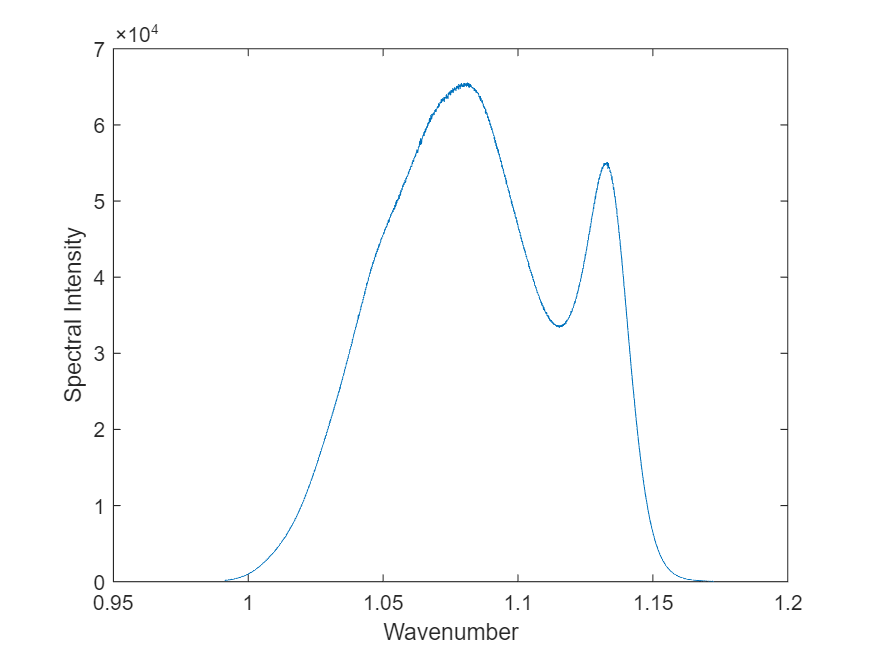

clear; clc;
format short g
%Original spectral interference signal
handle  = OCTFileOpen('Default_0193_Mode2D.oct');
NrRawData = OCTFileGetNrRawData(handle);
[RawData, Spectrum] = OCTFileGetRawData(handle, 0);
load('Wavelength.mat','Wavelength');
intensity = zeros(1,length(Spectrum));
wavelength = zeros(1,length(Wavelength));
for i = 1:length(Wavelength)
    wavelength(length(wavelength)+1-i) = Wavelength(i);
    intensity(length(intensity)+1-i) = Spectrum(i);
end
%波长映射到波数
sigma = 1./wavelength;
%波数均匀采样
sigma_inter = linspace(sigma(1),sigma(end),length(sigma)); 
%光谱强度三次样条插值
intensity_inter = spline(sigma,intensity,sigma_inter);
figure(4);plot(sigma_inter,intensity_inter);
xlabel('Wavenumber');ylabel('Spectral Intensity');

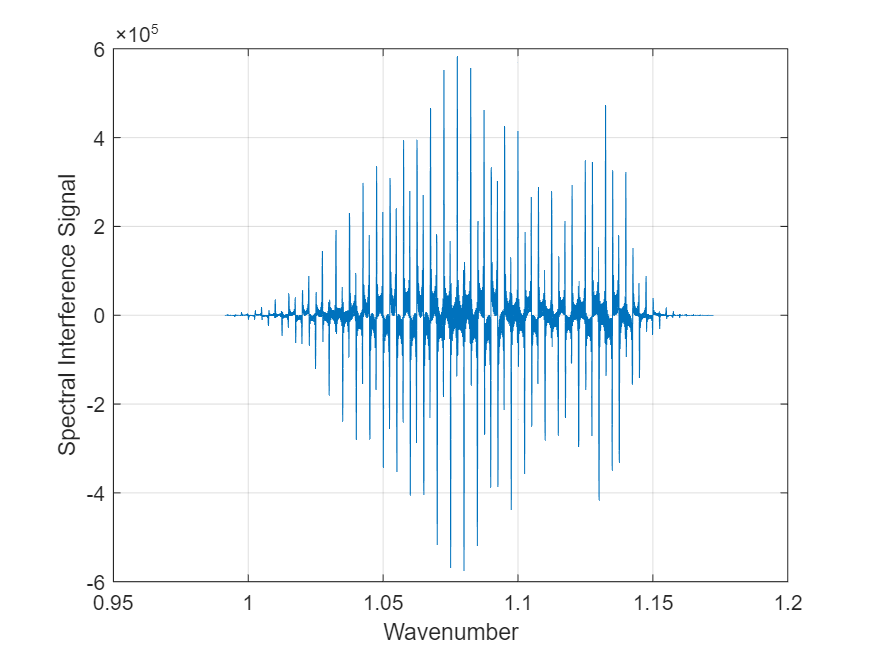

%光谱干涉信号S(\sigma) = A(\sigma)*cos(4\pi*(z-z0)*\sigma-4\pi*T*n(\sigma)*\sigma)
spec_signal = intensity_inter;

%设置参数：
z1 = [300 500 700 900 1100 1300 1500 1700 1900 2100];
z0 = 0;
T = 20000;
%加入色散
%色散公式
lambda = 1./sigma_inter;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./...
        (lambda.^2-103.560653)+(0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
%%存在问题
signalSum = zeros(1,length(sigma_inter));
%加入样品色散
for i = 2:length(z1)
interference_signal = spec_signal.*cos(4*pi*(z1(i)-z0).*sigma_inter-4*pi.*index*T.*...
    sigma_inter);%+2*spec_signal;
signalSum = signalSum + interference_signal;
end
%%
interference_signal1 = signalSum;
interference_signal = signalSum;
figure(5);plot(sigma_inter,interference_signal);
xlabel('Wavenumber');ylabel('Spectral Interference Signal');

%对光谱进行傅里叶变换
Nfft = 2^20;
fft_signal = fft(interference_signal,Nfft);
interference_signal = fftshift(fft_signal);
deltaSigma = (sigma_inter(end)-sigma_inter(1))/(length(sigma_inter)-1);
deltaZ = 1/(2*Nfft*deltaSigma);
z = (1:Nfft)*deltaZ;
intensity_fft = abs(interference_signal);
% angle_fft = angle(interference_signal);
%坐标变换
z = z-z(end)/2;
% figure(6);
intensity_fft = intensity_fft(length(intensity_fft)/2+1:end);
z = z(length(z)/2+1:end);
grid

threshold = max(intensity_fft)/1.2;
findpeaks(intensity_fft,z,'MinPeakHeight',threshold,'Annotate','extents')
[pks,locs,w,p] = findpeaks(intensity_fft,z,'MinPeakHeight',threshold,...
                'Annotate','extents')

pks =     1.3394    1.3401    1.3399    1.3404    1.3403    1.3402    1.3399    1.3400    1.3403


locs =     0.1084    0.3084    0.5084    0.7084    0.9084    1.1084    1.3084    1.5084    1.7084


w =    35.5007   35.4937   35.4957   35.4857   35.4856   35.4820   35.4747   35.4825   35.4542


p =     1.3393    1.3400    1.3399    1.3404    1.3401    1.3402    1.3397    1.3400    1.3403


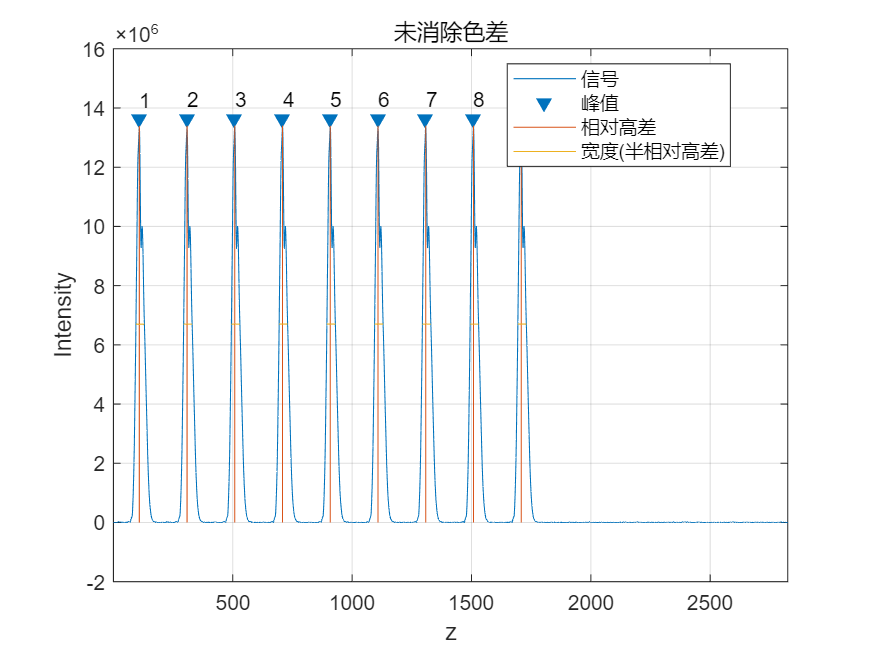

text(locs,pks+pks/15,num2str((1:numel(pks))'));
xlabel('z');ylabel('Intensity');title("未消除色差");

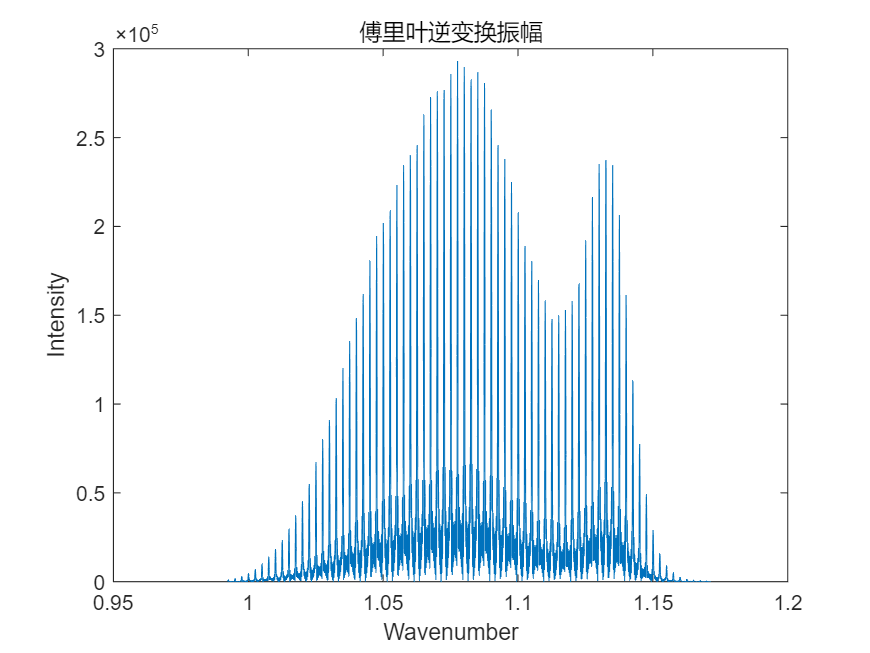

% figure(7);plot(z,unwrap(angle_fft));

%傅里叶逆变换
ifft_signal = fft_signal(1:length(fft_signal)/2);
% Nfft = 2^20;
ifft_signal = ifft(ifft_signal,Nfft);
interference_signal = ifftshift(ifft_signal);
deltaz = (z(end)-z(1))/(length(z)-1);
deltasigma = 1/(2*Nfft*deltaz);
sigma = (1:Nfft)*deltasigma;
intensity_ifft = abs(interference_signal);
angle_ifft = angle(interference_signal);
%坐标变换
sigma = sigma-sigma(end)/2+sigma_inter(1);
[~, indix_min] = min(abs(sigma-sigma_inter(1)-0.001));%sigma_inter(1)
[~, indix_max] = min(abs(sigma-sigma_inter(end)+0.001));%sigma_inter(end)
figure(6);plot(sigma(indix_min:indix_max),intensity_ifft(indix_min:indix_max));
xlabel('Wavenumber');ylabel('Intensity');title("傅里叶逆变换振幅")

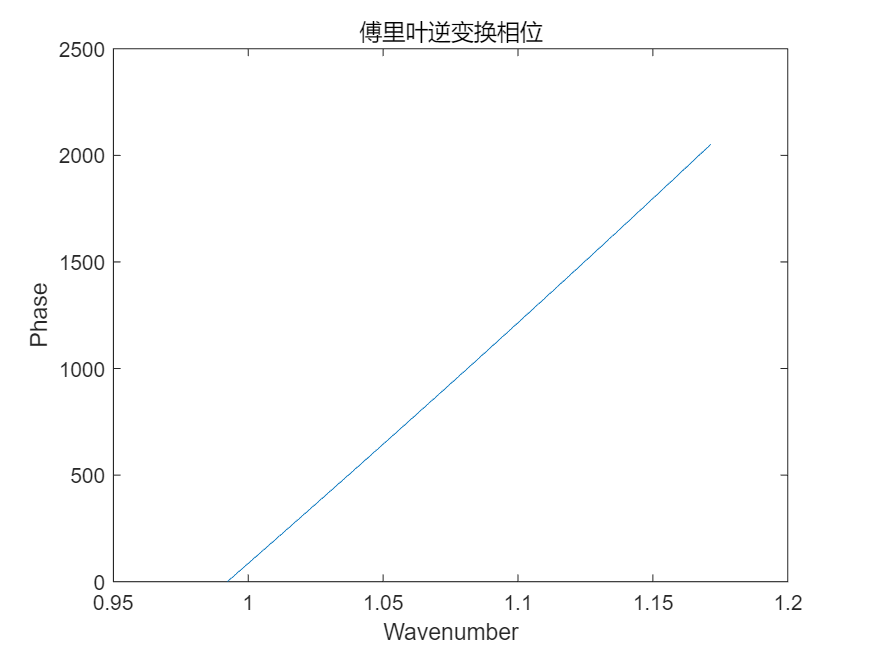

sigma = sigma(indix_min:indix_max);angle_fit = unwrap1(unwrap(...
        angle_ifft(indix_min:indix_max)));

%%%存在问题
derivaAng = deriva(angle_fit,deltasigma);
angle_fit(find(derivaAng<0):end) = angle_fit(find(derivaAng<0):end)+pi;
figure(7);plot(sigma,angle_fit);
xlabel('Wavenumber');ylabel('Phase');title("傅里叶逆变换相位")

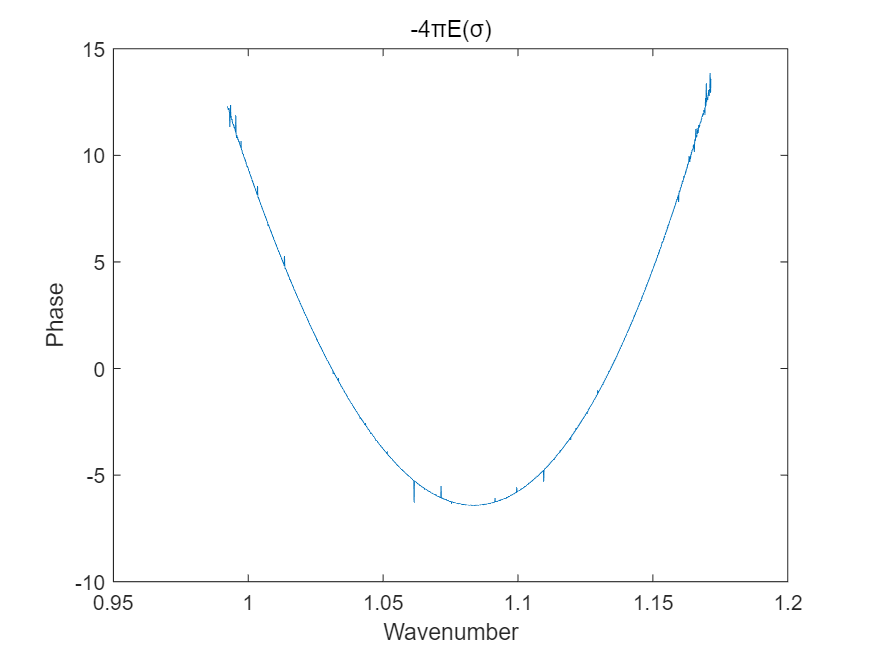




%数据拟合,得到4*pi*E = ang_fit-angle_fit
poly = polyfit(sigma,angle_fit,1);
ang_fit = polyval(poly,sigma);
plot(sigma,angle_fit-ang_fit);
xlabel('Wavenumber');ylabel('Phase');title("-4\piE(\sigma)");

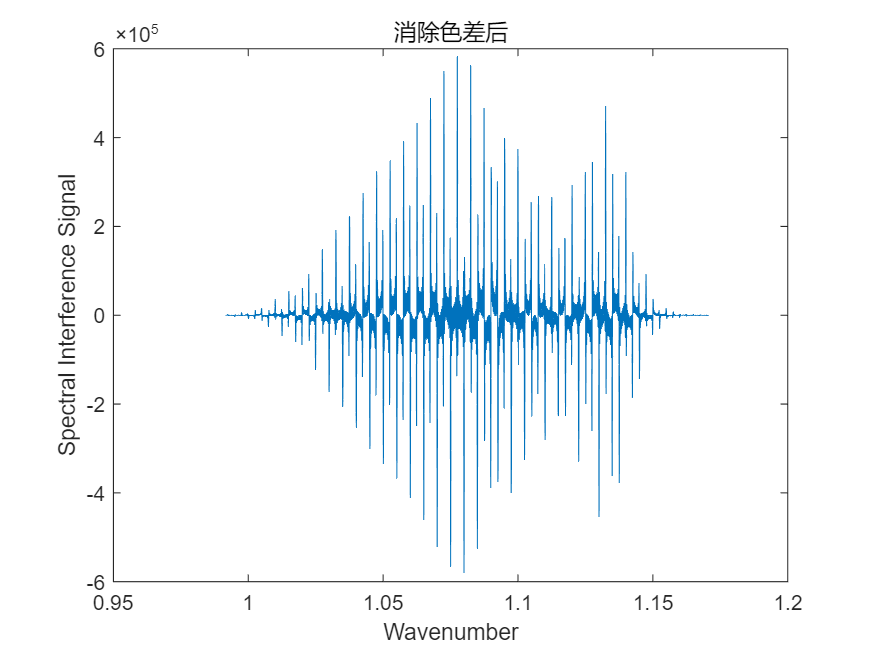


%----------------------------------------------------------------------------------------
% 求系数C
N = 2.5*10^3;
AMV = zeros(1,N);
AF = zeros(1,N);
SF = zeros(1,N);
% for i = 1:N
%  C= i*10^-6;
C = 705*10^-6;
%将sigma用sigma+C*E(sigma)替代
sigma_inter1 = sigma+C*(angle_fit-ang_fit)/(-4*pi);
%插值求得处理后的干涉信号,需要修正，首尾坐标选取sigma_inter、sigma_inter1中合适的值
sigma_find = (sigma_inter1>=sigma_inter(1) & sigma_inter1 <=sigma_inter(end));
sigma_inter1 = sigma_inter1(sigma_find);
signal_C = interp1(sigma_inter,interference_signal1,sigma_inter1,'spline');
plot(sigma_inter1,signal_C)
xlabel('Wavenumber');ylabel('Spectral Interference Signal');title("消除色差后");


%对光谱进行傅里叶变换
Nfft = 2^20;
fft_signal = fft(signal_C,Nfft);
interference_signal = fftshift(fft_signal);
deltaSigma = (sigma_inter1(end)-sigma_inter1(1))/(length(sigma_inter1)-1);
deltaZ = 1/(2*Nfft*deltaSigma);
z = (1:Nfft)*deltaZ;
intensity_fft = abs(interference_signal);
angle_fft = angle(interference_signal);

%坐标变换
z = z-z(end)/2;
z = z(length(z)/2+1:end);
intensity_fft = intensity_fft(length(intensity_fft)/2+1:end);
% plot(z,intensity_fft);
threshold = max(intensity_fft)/6;
findpeaks(intensity_fft,z,'MinPeakProminence',threshold,'MinPeakDistance',50,...
'Annotate','extents');
[pks,locs,w,p] = findpeaks(intensity_fft,z,'MinPeakProminence',threshold,...
                'MinPeakDistance',50,'Annotate','extents')

pks =     1.4027    1.5514    1.6972    1.7916    2.1221    2.6866    3.1253    3.1183    2.6428


locs =     0.1081    0.3075    0.5071    0.7068    0.9121    1.1114    1.3111    1.5110    1.7109


w =    31.9728   25.7724   21.1834   16.6146   12.9017    7.6951    5.5167    5.4672    7.5264


p =     1.4025    1.5507    1.6971    1.7905    2.1218    2.6862    3.1252    3.1182    2.6425


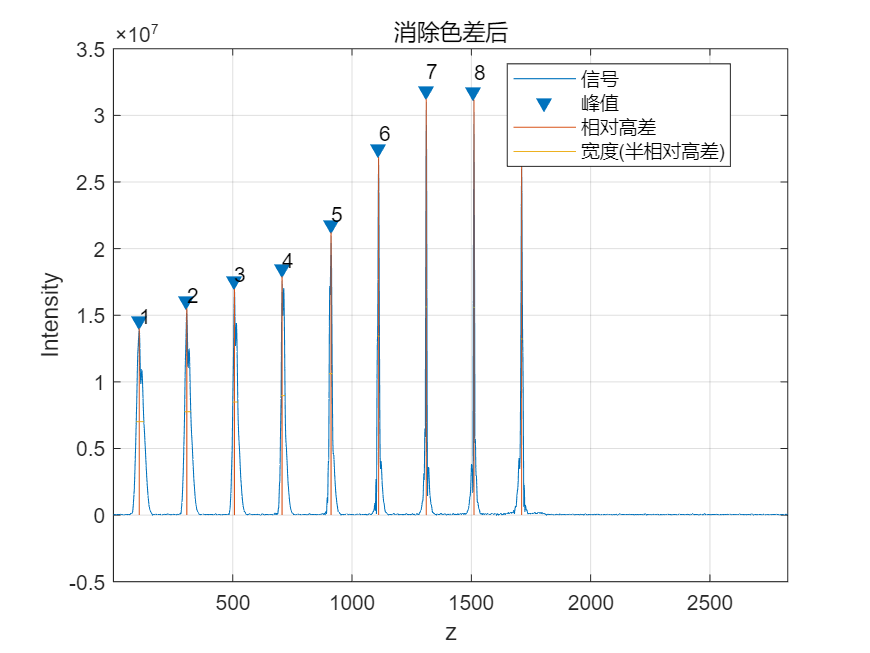

text(locs,pks+pks/15,num2str((1:numel(pks))'));
xlabel('z');ylabel('Intensity');title("消除色差后");

wdt = fwhm(intensity_fft,z,pks,locs,max(intensity_fft)/15)

wdt =    31.9781   25.7817   21.1842   16.6206   12.9025    7.6979    5.5168    5.4674    7.5278


% %计算最大值的平均值 (AMV)
% AMV(i) = mean(pks);
% %计算FWHMs 的平均值
% AF(i) = mean(wdt);
% %计算FWHMs的标准差
% SF(i) = std(wdt);
% % end
% plot((10^-6)*(1:N),AMV);xlim([0 1.3]);
% plot((10^-6)*(1:N),AF);xlim([0 1.3]);
% plot((10^-6)*(1:N),SF);xlim([0 1.3]);



function p = unwrap1(p)
%再次解包裹
x = p(1);
for n = 2:length(p)
    diff = p(n)-x;
    if diff <= -pi/4
        x = p(n);
       p(n) = p(n-1)+diff+pi;
    elseif diff <0 && diff > -pi/4 
       x = p(n); 
       p(n) = p(n-1)+diff;
    elseif diff >= 3*pi/4 
        x = p(n); 
        p(n) = p(n-1)+diff-pi;
    elseif diff >= 0 && diff < 3*pi/4
        x = p(n); 
        p(n) = p(n-1)+diff;
    end
end
end

%求一阶导数
function q = deriva(p,h)
q = zeros(1,length(p));
for i = 2:length(p)-1
    q(i) = (p(i+1)-p(i-1))/(2*h);
end
q(1) = q(2);q(end) = q(end-1);
end

%简单计算FWHM,threshold是划分区域的阈值
function wdt = fwhm(data,x,pks,locs,threshold)
%平滑处理
% data = smoothdata(data,'sgolay',4); 
% plot(x,data);
idx = diff(sign(data -threshold));
xlocs = x(find(idx));
wdt = zeros(1,numel(locs));
xfwhm = zeros(1,2);
% plot(wdt,data(idx),'*r')
for i = 1:length(locs)
    idx = find(diff(sign(xlocs-locs(i))));
    idx1 = find(~(x-xlocs(idx)));
    idx2 = find(~(x-xlocs(idx+1)));
    data1 = data(idx1:idx2);
    x1 = x(idx1:idx2);
    idx = find(diff(sign(data1-pks(i)/2)));
    for n = 1:numel(idx)
        idxrng = idx(n)-2:idx(n)+2;
        xfwhm(1,n) = interp1(data1(idxrng), x1(idxrng), pks(i)/2, 'pchip');
    end
    wdt(i) = xfwhm(end)-xfwhm(1);
end
end

function sam_dis = refidx(z,i,index,sigma)
sam_dis = 0;
for i = i:-1:2
    sam_dis = 4*pi.*index*(z(i)-z(i-1)).*sigma+sam_dis;
end
end